%registration images
%green 1040 aligned to calcium 920

reg_obj = imregcorr(green, calcium);
T = reg_obj.T;
aligned_green = imwarp(green, affine2d(T), 'OutputView', imref2d(size(green)));
imwrite(aligned_green, ([path,'aligned_green.tif']), 'tif');

%red 1040 aligned to green 1040
aligned_red1040 = imwarp(red, affine2d(T), 'OutputView', imref2d(size(red)));
imwrite(aligned_red1040, ([path,'aligned_red1040.tif']), 'tif');

%red 890 aligned to red1040 and used to align Blue890 
reg_obj = imregcorr(red890, aligned_red1040);
T = reg_obj.T;
aligned_red890 = imwarp(red890, affine2d(T), 'OutputView', imref2d(size(green)));
imwrite(aligned_red890, ([path,'aligned_red890.tif']), 'tif');


%import ROI from cellpose mode "save outlines as text for imagej
opts = delimitedTextImportOptions("NumVariables", 68);
opts.DataLines = [1, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts = setvaropts(opts, ["VarName67", "VarName68"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["VarName67", "VarName68"], "ThousandsSeparator", ",");

% Import the data
alignedbluecpoutlines = readtable...
    ("/Users/platel/Desktop/exp/aurelie/175 25-11-2022/221125_plane1_all/aligned_blue_cp_outlines.txt", opts);
alignedbluecpoutlines = table2array(alignedbluecpoutlines+1);


opts = delimitedTextImportOptions("NumVariables", 82);
opts.DataLines = [1, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68", "VarName69", "VarName70", "VarName71", "VarName72", "VarName73", "VarName74", "VarName75", "VarName76", "VarName77", "VarName78", "VarName79", "VarName80", "VarName81", "VarName82"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts = setvaropts(opts, ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68", "VarName69", "VarName70", "VarName71", "VarName72", "VarName73", "VarName74", "VarName75", "VarName76", "VarName77", "VarName78", "VarName79", "VarName80", "VarName81", "VarName82"], "ThousandsSeparator", ",");
alignedredcpoutlines = readtable...
    ("/Users/platel/Desktop/exp/aurelie/175 25-11-2022/221125_plane1_all/aligned_red1040_cp_outlines.txt", opts);
alignedredcpoutlines = table2array(alignedredcpoutlines);

%transformation masque imagej en cellule cooblue(ncell, npixel, 1=x, 2=y)
[nbroiblue count]=size (alignedbluecpoutlines);

for ncell=1:nbroiblue
    n=0;
    for pix=1:2:sum (~isnan(alignedbluecpoutlines(ncell,:)))  % le width de chaque ligne en enlevant les NaN
        n=n+1;
        cooblue(ncell,n,1) = {alignedbluecpoutlines(ncell,pix)};
        cooblue(ncell,n,2) = {alignedbluecpoutlines(ncell,pix+1)};
    end
end

[nbroired count]=size (alignedredcpoutlines);

for ncell=1:nbroired
    n=0;
    for pix=1:2:sum (~isnan(alignedredcpoutlines(ncell,:)))  % le width de chaque ligne en enlevant les NaN
        n=n+1;
        coored(ncell,n,1) = {alignedredcpoutlines(ncell,pix)};
        coored(ncell,n,2) = {alignedredcpoutlines(ncell,pix+1)};
    end
end

%making  calcium mask (binary) for comparison

% gcamp_mask=zeros(NCell,512,512)
for n=1:NCell
    x=double(cell2mat(Coomasqx(n)));
    y=double(cell2mat(Coomasqy(n)));
    gcamp_mask(n,:,:) = poly2mask(x, y, 512, 512);
end

%making  blue mask (binary) for comparison
for n=1:nbroiblue
    x=cell2mat(cooblue(n,:,1));
    y=cell2mat(cooblue(n,:,2));
    blue_mask(n,:,:) = poly2mask(x, y, 512, 512);
end

%making  red mask (binary) for comparison
for n=1:nbroired
    x=cell2mat(coored(n,:,1));
    y=cell2mat(coored(n,:,2));
    red_mask(n,:,:) = poly2mask(x, y, 512, 512);
end



tic
gcamp_mask_reshaped = reshape(gcamp_mask, NCell, []);
blue_mask_reshaped = reshape(blue_mask, nbroiblue, []);

intersection = zeros(NCell, nbroiblue);
union = zeros(NCell, nbroiblue);

for m = 1:NCell
    gcamp_tmp = gcamp_mask_reshaped(m, :);

    parfor n = 1:nbroiblue
        blue_tmp = blue_mask_reshaped(n, :);

        % Calculate intersection and union
        intersection(m, n) = sum(gcamp_tmp & blue_tmp);
        union(m, n) = sum(gcamp_tmp | blue_tmp);
    end
end

% Calculate IoU
IoUblue = intersection ./ union;
toc

Elapsed time is 303.421739 seconds.


tic
gcamp_mask_reshaped = reshape(gcamp_mask, NCell, []);
red_mask_reshaped = reshape(red_mask, nbroired, []);

intersection = zeros(NCell, nbroired);
union = zeros(NCell, nbroired);

for m = 1:NCell
    gcamp_tmp = gcamp_mask_reshaped(m, :);

    parfor n = 1:nbroired
        red_tmp = red_mask_reshaped(n, :);

        % Calculate intersection and union
        intersection(m, n) = sum(gcamp_tmp & red_tmp);
        union(m, n) = sum(gcamp_tmp | red_tmp);
    end
end

% Calculate IoU
IoUred = intersection ./ union;
toc

Elapsed time is 403.301143 seconds.


% tic
% % Calculate intersection and 
% 
% 
% for m=1:NCell
% 
%     gcamp_tmp=reshape(gcamp_mask(m,:,:),512,512);
%     gcamp_tmp=gcamp_tmp(:);
% 
%     parfor n=1 :nbroiblue
% 
%         blue_tmp=reshape(blue_mask(n,:,:),512,512);
%         blue_tmp=blue_tmp(:);
% 
%         % intersection(m,n,:) = sum( reshape(gcamp_mask(m,:,:),512,512) & reshape(blue_mask(n,:,:),512,512) ) ;
%         % union(m,n,:) = sum( reshape(gcamp_mask(m,:,:),512,512) | reshape(blue_mask(n,:,:),512,512) );
%         intersection = sum(gcamp_tmp & blue_tmp) ;
%         union = sum(gcamp_tmp | blue_tmp);
% 
%         % Calculate IoU
%         % IoU(m,n) = intersection(m,n) / union(m,n);
%         IoU(m,n) = intersection / union;
%     end
% end
% toc
% figure
% hold on
% for n=1:NCell
%     plot(IoU(n,:),'DisplayName','IoU')
% end

## Threshold IoU and plot

threshold = 0.1; % Adjust the threshold based on your requirements

% Compare IoU with the threshold
[idxgcampblue idxblue]=find (IoUblue>threshold);
threshold = 0.2;
[idxgcampred idxred]=find (IoUred>threshold);


## plot

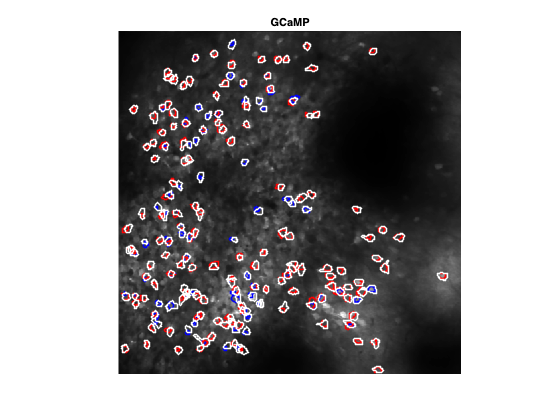

figure
imagesc(calcium);
colormap (gray)
clim ([0 200])
hold on

    % 
% x=cell2mat(outline_bluex(n));
% y=cell2mat(outline_bluey(n));
for n=transpose(idxblue)
    x=cell2mat(cooblue(n,:,1));
    y=cell2mat(cooblue(n,:,2));
    %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    plot(x, y, '.', 'MarkerSize', 4,"Color",'b');
end
for n=transpose(idxgcampblue)
   % plot(centroid_blue(n,1),centroid_blue(n,2),'r.')
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
   plot(x, y, '.', 'MarkerSize', 4,"Color",'w');
end
for n=transpose(idxred)
    x=cell2mat(coored(n,:,1));
    y=cell2mat(coored(n,:,2));
    %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    plot(x, y, '.', 'MarkerSize', 4,"Color",'r');
end
for n=transpose(idxgcampred)
   % plot(centroid_blue(n,1),centroid_blue(n,2),'r.')
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
   plot(x, y, '.', 'MarkerSize', 4,"Color",'w');
end






axis image
axis off
hold off
title ('GCaMP')

name=[namefull 'blue_w_mask.png'];

% hausdorff
% jaccard
% cobluex(1,1)
% normxcorr2

% for ncell=1:nbroiblue

mask_blue = imfill(cooblue(1), 'holes');


% Step 1: Create binary masks for each cell
cell1Mask = zeros(imageHeight, imageWidth);
cell2Mask = zeros(imageHeight, imageWidth);

% Set pixels belonging to cell 1 to 1
cell1Mask(sub2ind([imageHeight, imageWidth], cell1Y, cell1X)) = 1;

% Set pixels belonging to cell 2 to 1
cell2Mask(sub2ind([imageHeight, imageWidth], cell2Y, cell2X)) = 1;

% Step 2: Compute normalized cross-correlation
corrMatrix = normxcorr2(cell1Mask, cell2Mask);

% Step 3: Analyze the correlation matrix
[maxValue, maxIndex] = max(corrMatrix(:));
[maxRow, maxCol] = ind2sub(size(corrMatrix), maxIndex);

% Determine the degree of overlap based on the maximum correlation value
overlapPercentage = maxValue * 100;  % Scale the correlation value to a percentage


% Create binary masks for each cell
cell1Mask = zeros(imageHeight, imageWidth);
cell2Mask = zeros(imageHeight, imageWidth);


% Set pixels belonging to cell 1 to 1
cell1Mask(sub2ind([imageHeight, imageWidth], coo, cell1X)) = 1;

% Set pixels belonging to cell 2 to 1
cell2Mask(sub2ind([imageHeight, imageWidth], cell2Y, cell2X)) = 1;

% Compute intersection over union (IoU)
intersection = cell1Mask & cell2Mask;
union = cell1Mask | cell2Mask;
iou = sum(intersection(:)) / sum(union(:));

% Calculate the overlap percentage
overlapPercentage = iou * 100;


figure
imagesc(aligned_blue);
colormap (gray)
clim ([0 300])
hold on
% 
for n=1:nbroiblue
    % 
    % x=cell2mat(outline_bluex(n));
    % y=cell2mat(outline_bluey(n));
    x=cell2mat(cooblue(n,:,1));
    y=cell2mat(cooblue(n,:,2));
    %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
   plot(x, y, '.', 'MarkerSize', 4,"Color",'b');
   % plot(centroid_blue(n,1),centroid_blue(n,2),'r.')

end

axis image
axis off
hold off
title ('blue')
name=[namefull 'blue_w_mask.png'];
%exportgraphics(gcf,name,'Resolution',600);